# Демодуляция. Часть 1.

# Single Sideband Suppressed Carrier 

# (AM-SSB-SC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Когерентная демодуляция

Рассмотрим когерентный способ демодуляции однополосного АМ-сигнала с подавленной несущей. Для этого принятый сигнал нужно смешать (перемножить) с колебанием, которое является копией несущей. Затем результат необходимо пропустить через фильтр нижних частот (ФНЧ). Схема когерентного демодулятора представлена ниже:

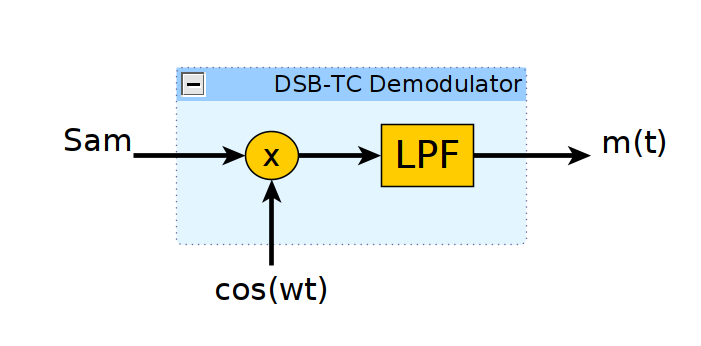

Для примера рассмотрим USB сигнал. Результаты для LSB получаются таким же образом и отличаются только знаком перед квадратурной частью принимаемого однополосного сигнала.В аналитическом виде описанные выше преобразования можно представить следующим образом. Пусть принятый однополосный сигнал имеет вид:

$s_{\textrm{am}} \left(t\right)=m\left(t\right)\cdot \cos \left(2\pi f_c t\right)-m_H \left(t\right)\cdot \sin \left(2\pi f_c t\right)$,

где $m\left(t\right)$ - информационное сообщение, $m_H \left(t\right)$ - преобразование Гильберта от сообщения, $f_c$ - частота несущей.

После перемножения с гармоничеким сигналом, частота и фаза которого совпадают с несущей, получим:


$$s_{\textrm{mix}} \left(t\right)=\left\lbrack m\left(t\right)\cdot \cos \left(2\pi f_c t\right)-m_H \left(t\right)\cdot \sin \left(2\pi f_c t\right)\right\rbrack \cdot \cos \left(2\pi f_c t\right)=$$


$m\left(t\right)\cdot \cos \left(2\pi f_c t\right)\cdot \cos \left(2\pi f_c t\right)-m_H \left(t\right)\cdot \sin \left(2\pi f_c t\right)\cdot \cos \left(2\pi f_c t\right)$.

Вспомнив правило произведения косинусов и синусов, можем записать результат умножения в виде:

$s_{\textrm{mix}} \left(t\right)=\frac{1}{2}m\left(t\right)+\frac{1}{2}m\left(t\right)\cdot \cos \left(2\pi \cdot 2f_c \cdot t\right)-\frac{1}{2}m_H \left(t\right)\cdot \sin \left(2\pi \cdot 2f_c \cdot t\right)$.

Таким образом, сигнал на выходе смесителя явялется суммой инфомационного сообщения, а также сообщения и его преобразования Гильберта на удвоенной частоте несущей $2f_c$. После пропускания данной суммы через ФНЧ, слагаемые на удвоенной частоте исчезнут, и мы получим:

$s_{\textrm{LPF}} \left(t\right)=\frac{1}{2}m\left(t\right)$.

То есть, восстановленный сигнал является масштабированной копией исходного сообщения. 

Сложность при таком методе демодуляции заключается в том, что колебание в смесителе должно точно совпадать по частоте и фазе с несущей. Очевидно, что на практике генераторы на передающей и приемной сторонах не могут быть абсолютно идентичными. Между ними всегда есть некоторая расстройка. Рассмотрим вляние такого рассогласования на качество  демодуляции. Пусть рассогласование по частоте и фазе между колебаниями в смесителе и несущей равны $\Delta f$ и $\Delta \phi$ соотвветственно. В этом случае на выходе смесителя получим:


$$s_{\textrm{mix}} \left(t\right)=\left\lbrack m\left(t\right)\cdot \cos \left(2\pi f_c t\right)-m_H \left(t\right)\cdot \sin \left(2\pi f_c t\right)\right\rbrack \cdot \cos \left(2\pi \left(f_c +\Delta f\right)t+\Delta \phi \right)=$$



$$=\frac{1}{2}m\left(t\right)\cdot \cos \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)-\frac{1}{2}m_H \left(t\right)\cdot \sin \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)+\textrm{слагаемые}\;с\;\textrm{удвоенной}\;\textrm{частотой}\ldotp$$


После ФНЧ слагаемые на удвоенной частоте исчезнут:

$s_{\textrm{LPF}} \left(t\right)=\frac{1}{2}m\left(t\right)\cdot \cos \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)-\frac{1}{2}m_H \left(t\right)\cdot \sin \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)$.

Таким образом, как и для случая DSB  сигнала, восстановленное сообщения будет масштабиравано на множитель $\cos \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)$, амплитуда которого изменятся с частотой, равной расстройке по частоте. По мимо этого после фильтрации останется еще одно слагаемое, равное $\frac{1}{2}m_H \left(t\right)\cdot \sin \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)$. Оно также будет вносить искажения в восстановленное сообщение.

Ниже представлен скрипт, который демонстрирует когерентный метод демодуляции для аудиосообщения на несущей частоте 60кГц. С помощью переменных FreqOffset и PhaseOffset можно задать расстройку по частоте и фазе и на слух оценить оскажения сигнала. Переменная ModulationMethod задает вид модуляции (USB или LSB).

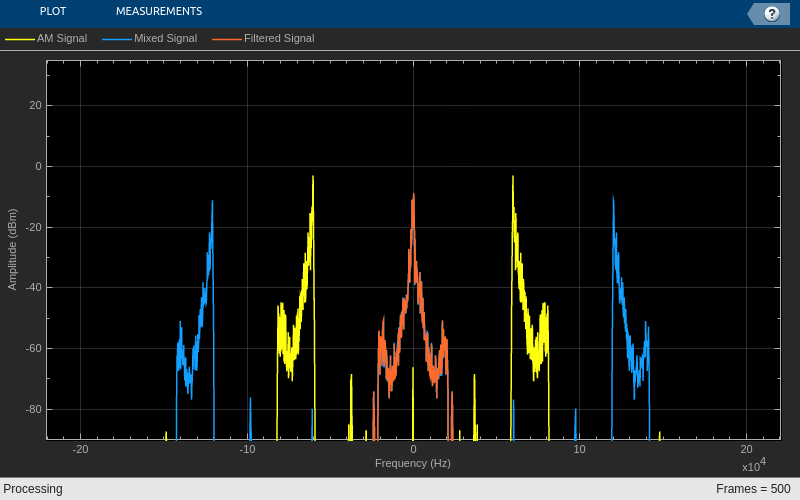

clc; clear; close all;
addpath('matlab/DSB_SC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

FreqOffset = 500;             % расстройка по частоте (Hz)
PhaseOffset = 90 * pi/180;   % расстройка по фазе (градусы)

% выбор метода модуляции
ModulationMethod = "USB";  

% объект для считываения отсчетов аудиофайла
if (ModulationMethod == "USB")
    WaveFileName = 'wav/Audio_USB_SC.wav';
else
    WaveFileName = 'wav/Audio_LSB_SC.wav';
end
AudioReader = dsp.AudioFileReader(...
    WaveFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', Fc + FreqOffset,...
    'PhaseOffset', pi/2 + PhaseOffset...
    );

% расчет коэффициентов фильтра нижних частот
H = Audio_Lowpass_FIR_Coeff();

% создание объекта для фильтрации
LowpassFIR = dsp.FIRFilter(H.Numerator);

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Mixed Signal', 'Filtered Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* Carrier();

    % фильтрация сигнала
    BasebandSignal = LowpassFIR(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal MixedSignal BasebandSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым цветом обозначен спектр принимаемого однополосного сигнала. Синим - спектр на выходе смесителя. Можно увидеть, что он состоит из информационного сообщения и спектральных составляющих на удвоенной частоте несущей. После фильтрации остается только информационное сообщение (красный цвет).

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить искажения аудиосигнала из-за рассогласования по фазе и частоте. В отличие от DSB сигнала при расстройке по фазе сигнал слышится также хорошо, и он не искажен. Это связано с тем, что теперь в сигнале после фильтрации присутствует слагаемое $\frac{1}{2}m_H \left(t\right)\cdot \sin \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)$. При нулевой расстройке по фазе оно равно нулю, и возврастает при увеличении расстройки. То есть, при уменьшении первого слагаемого с сообщением, слагаемое с его преобразованием Гильберта растет, и наоборот. Сигналы $m\left(t\right)$ и $m_H \left(t\right)$имеют одинакове амплитудные спектры и различаются лишь фазой. Так как человеческий слух реагирует только на амплитудный спектр, для нас эти сигналы кажутся одинаковыми. Расстройка по частоте приводит к ухудшению качества и появлению свистящих звуков и биений.

В файле S*SB_SC_Receiver_Part_1_1.slx* представлена Simulink модель когерентного демодулятора, который ранее был реализован ввиде скрипта. С помощью переключателя можно выбирать между USB и LSB сигналами.

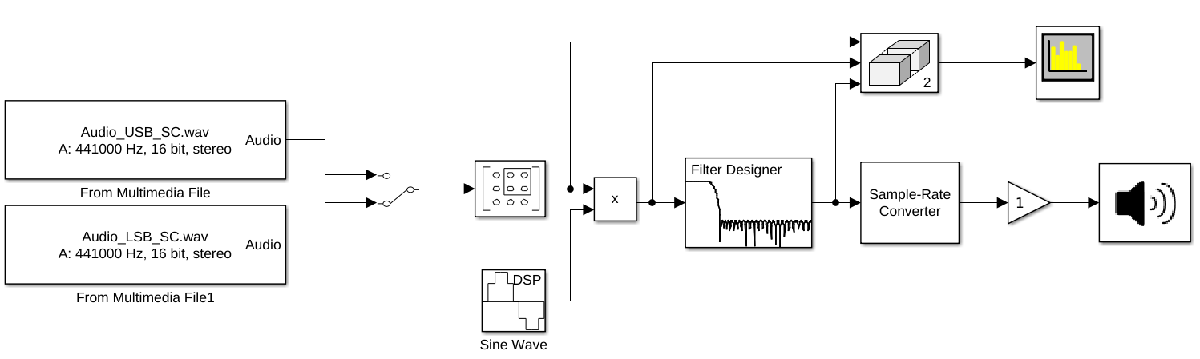

### 2. Когерентная демодуляция при квадратурном приеме

В случае, когда прием однополостного сигнала осуществляется квадратурным способом (например почти во всех SDR-приемниках), структуру когерентного демодулятора можно упростить:

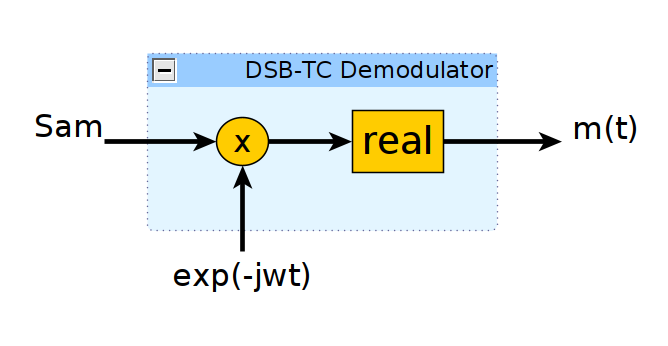

То есть, принятый однополосный сигнал нужно умножить на мнимую экспоненту, а потом просто выделить действительную часть. Далее для примера рассмотрим случай USB сигнала. В аналитическом виде описанные выше преобразования можно представить следующим образом. Пусть принятый однополосный сигнал имеет вид:

$s_{\textrm{am}} \left(t\right)=m_A \left(t\right)\cdot e^{2\pi f_c t}$,

где, как и ранее, $m_A \left(t\right)=m\left(t\right)+j\cdot m_H \left(t\right)$ - аналитический сигнал, $m\left(t\right)$ - информационное сообщение, $m_H \left(t\right)$ - преобразование Гильберта от сообщения, $f_c$ - частота несущей.

После умножения на мнимую экспоненту, частота и фаза которой совпадает с несущей, получим:

$s_{\textrm{mix}} \left(t\right)=m_A \left(t\right)\cdot e^{2\pi f_c t} \cdot e^{-2\pi f_c t} =m_A \left(t\right)=m\left(t\right)+j\cdot m_H \left(t\right)$.

Выделение действительной части приведет к точному восстановлению информационного сообщения: 

$\textrm{Re}\left\lbrace s_{\textrm{mix}} \left(t\right)\right\rbrace =m\left(t\right)$.

Теперь рассмотрим, что произойдет при наличие раастройки по фазе и частоте. Сигнал на выходе смесителя можно представить в виде:

$s_{\textrm{mix}} \left(t\right)=m_A \left(t\right)\cdot e^{2\pi f_c t} \cdot e^{-2\pi \left(f_c +\Delta f\right)t-\Delta \phi } =m_A \left(t\right)\cdot e^{-2\pi \Delta \textrm{ft}-\Delta \phi }$.

После вычисления действительной части получим:

$\textrm{Re}\left\lbrace s_{\textrm{mix}} \left(t\right)\right\rbrace =m\left(t\right)\cdot \cos \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)-m_H \left(t\right)\cdot \sin \left(2\pi \Delta \textrm{ft}+\Delta \phi \right)$.

Данный результат совпадает с формулой, полученной в предыдущем разделе. Соответственно наличие расстройки по частоте и фазе будет приводить к аналогиным искажениям.

Ниже представлен скрипт для реализации когерентной демодуляции в случае квадратурного приема. С помощью переменных FreqOffset и PhaseOffset можно задать расстройку по частоте и фазе и на слух оценить оскажения сигнала. Переменная ModulationMethod задает вид модуляции (USB или LSB).

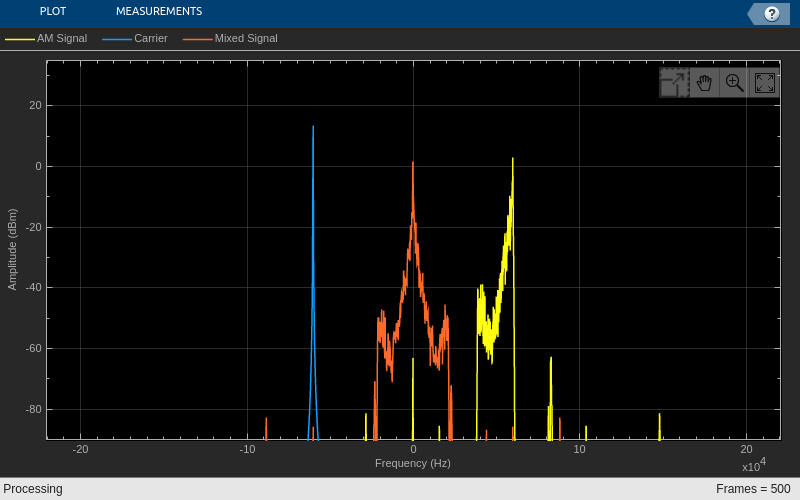

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

FreqOffset = 0;             % расстройка по частоте (Hz)
PhaseOffset = 0 * pi/180;   % расстройка по фазе (градусы)

% выбор метода модуляции
ModulationMethod = "LSB"; 

% объект для считываения отсчетов аудиофайла
if (ModulationMethod == "USB")
    WaveFileName = 'wav/Audio_USB_SC.wav';
else
    WaveFileName = 'wav/Audio_LSB_SC.wav';
end
AudioReader = dsp.AudioFileReader(...
    WaveFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', [Fc + FreqOffset, Fc + FreqOffset],...
    'PhaseOffset', [pi/2 + PhaseOffset, PhaseOffset]...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Mixed Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % получение несущей
    CarrierWave = Carrier();
    CarrierWave = CarrierWave(:,1) - 1j*CarrierWave(:,2);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* CarrierWave;
    MixedSignal = real(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(MixedSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal CarrierWave MixedSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым цветом обозначен спектр принимаемого  однополосного сигнала. Так как прием квадратурный, спектр сигнала комплексный и расположен только в положительной области частот. Синим цветом представлена мнимая экспонента, а красным - сигнал на выходе смесителя. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

В файле S*SB_SC_Receiver_Part_1_2.slx* представлена Simulink модель когерентного демодулятора в квадратурном случае. С помощью переключателя можно выбирать между USB и LSB сигналами.

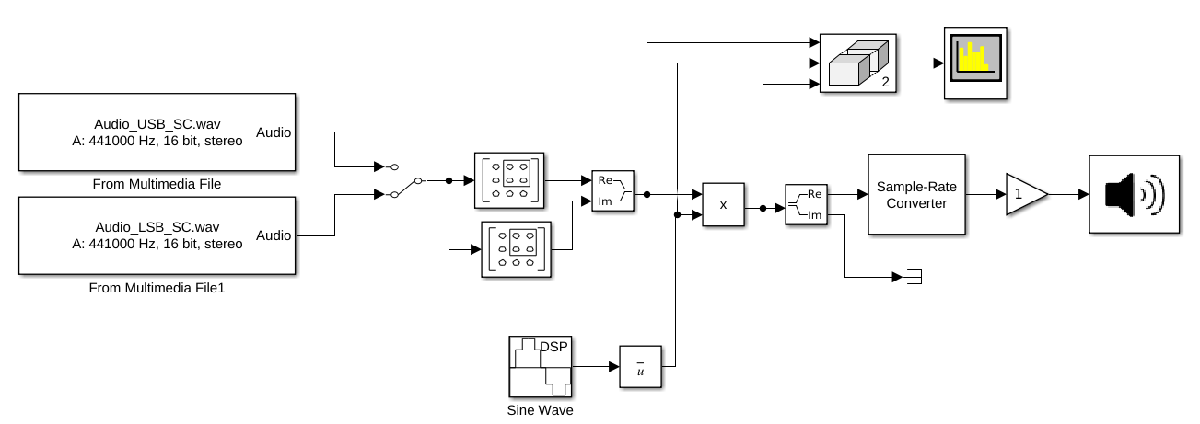

### 3. Некогерентная демодуляция однополосного сигнала с подавленной несущей

В случае однополосной амплитудной модуляции с подавленной несущей сама несущая не передается, что является преимуществом, так приводит к экономии мощности. Однако, с другой стороны это усложняет прием такого сигнала. Очевидно, что из-за наличия в сигнала слагаемого, равного преобразованию Гильберта от сообщения, огибающая сигнала не будет совпадать с сообщением. Таким образом, некогерентный демодулятор для приема сигнала с подавленной несущей применять нельзя. 

Убедимся в этом для случая квадратурного приема. Для получаения огибающей комплексного сигнала достаточно вычислить его модуль. Воспользуемся тем же скриптом, который рассмотривается в DSB TC Receiver Part 3. Скрипт представлен ниже:

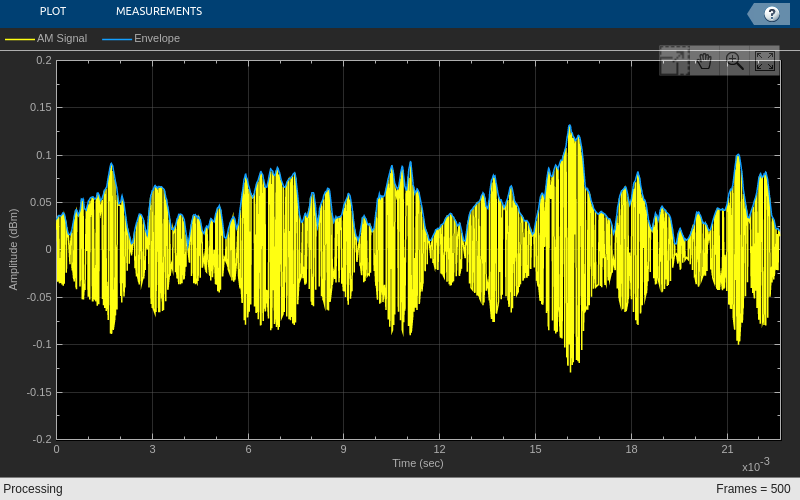

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации

% выбор метода модуляции
ModulationMethod = "LSB"; 

% объект для считываения отсчетов аудиофайла
if (ModulationMethod == "USB")
    WaveFileName = 'wav/Audio_USB_SC.wav';
else
    WaveFileName = 'wav/Audio_LSB_SC.wav';
end
AudioReader = dsp.AudioFileReader(...
    WaveFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-0.2, 0.2], ...
    'XLabel', 'Time (sec)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Envelope'}, ...
    'SampleIncrement', 1/SignalFs ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % вычисление амплитуды сигнала
    AbsAmSignal = abs(AmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(AbsAmSignal)];

    % вывод результатов на график
    Plotter([real(AmSignal) AbsAmSignal])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены временные диаграммы сигналов на входе (желтый цвет,  действительная составляющая принятого сигнала) и выходе (синий цвет) демодулятора. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно обнаружить явные искажения аудиосообщения, что подтверждает невозможность приема однополосного сигнала с подавленной несущей некогерентным способом. 

### 4. Когерентная демодуляция с помощью обычной фазовой автоподстройки частоты

Рассмотренный в DSB TC Receiver Part 2 способ востановления несущей с помощью PLL для сигнала с подавленной несущей так же не пременим. В принимаемом сигнале отсутствует в явном виде гармонический сигнал соответствующий несущей. Из-за этого фазовая автоподстройка частоты не может войти в режим синхронизации и точно подстроить частоту и фазу управляемого генератора. 

Убедимся в этом для случая квадратурного приема. Воспользуемся тем же скриптом, который рассмотривается в DSB TC Receiver Part 2. Скрипт представлен ниже:

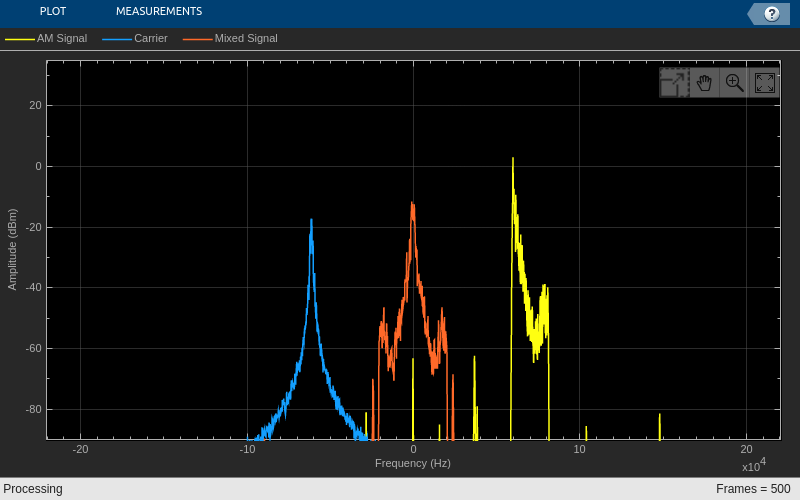

clc; clear; close all;
addpath('matlab/DSB_TC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% выбор метода модуляции
ModulationMethod = "USB"; 

% объект для считываения отсчетов аудиофайла
if (ModulationMethod == "USB")
    WaveFileName = 'wav/Audio_USB_SC.wav';
else
    WaveFileName = 'wav/Audio_LSB_SC.wav';
end
AudioReader = dsp.AudioFileReader(...
    WaveFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
AmPLL = AmComplexPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Mixed Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % восстанавливаем несущую
    [Carrier, Offset] = AmPLL(AmSignal);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* conj(Carrier);
    MixedSignal = real(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(MixedSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal conj(Carrier) MixedSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены сигналы в частотной области. Желтым цветом обозначен спектр принимаемого однополосного сигнала. Синим цветом обозначен сигнал на выходе NCO PLL, а красным - сигнал на выходе смесителя. Можно увидеть, что спектр на выходе NCO намного шире, чем на графике, показанном в DSB TC Receiver Part 2. Это свидетельствует о плохой синхронизации, так как сигнал на выходе NCO отличается от гармонического.

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух также можно обнаружить искажения аудиосообщения. Таким образом, качествено восстановить несущую, просто подав принятый однополосный сигнал на вход PLL, не получится.

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR